## Polar Overturning Conceptual Model

#### Live script to run experiments in paper and produce the figures.

#### twnh Aug, Sep '19, Jan–May '20

Housekeeping:

clear
close all
%parpool('MJSProfile1',84) 
if(isempty(gcp))
    %parpool('MJSProfile1',84)
    parpool('local',16) 
end

Exp 1: Northern hemisphere Fram Strait/Barents Sea Opening.

model1 = build_POC_model('NH_FSBSO_can') ;

 Solutions for experiment: [Exp.~1 Fram Strait+BSO] with file suffices: [NH_FSBSO_can]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:                      3.4000          |           35.0000          |            4.7500
 Atlantic Water to shelf:             3.4000          |           35.0000          |   0.1033   0.2697   0.6381
 Polar    Water:                     -1.8675          |           34.3235          |  -1.7018  -1.0838  -0.0000
 Overflow Water:             1.2077   1.4288   1.5674 |  34.9026  34.9552  35.0714 |  -4.7261  -3.6723  -3.0725
 Shelf    Water:            -1.9947  -2.0610  -2.2015 |  36.5013  37.6287  40.0000 |  -0.5860  -0.2297  -0.0751
 Ambient Water:                       1.6617          |           34.7768          |
 Sea ice:                           -10.0000

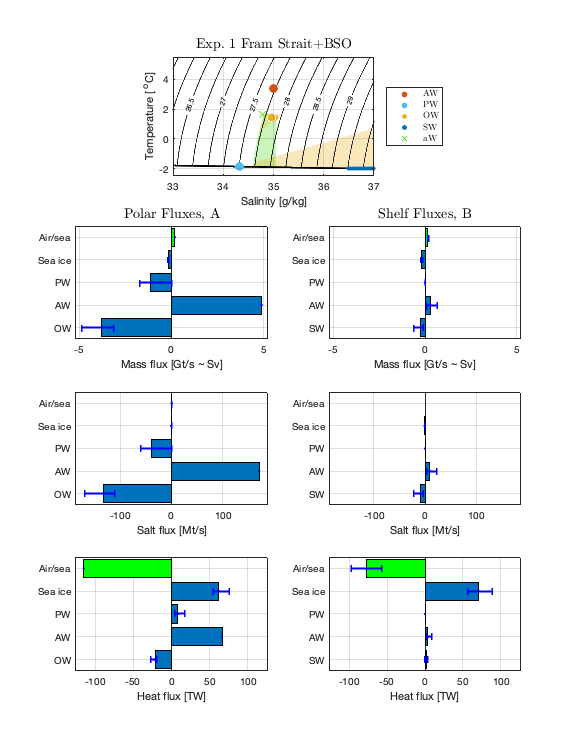

plot_POC_solution(model1)

Exp 2: Modified Northern hemisphere Fram Strait/Barents Sea Opening (higher Q).

model2 = build_POC_model('NH_FSBSO_mod') ;

 Solutions for experiment: [Exp.~2 Fram Strait+BSO high ${\cal Q}$] with file suffices: [NH_FSBSO_mod]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:                      3.4000          |           35.0000          |            4.7500
 Atlantic Water to shelf:             3.4000          |           35.0000          |   2.9485   3.3072   3.6928
 Polar    Water:                     -1.8675          |           34.3235          |  -1.8285  -0.9941  -0.0031
 Overflow Water:            -1.8932  -1.4517  -1.0728 |  34.7652  34.8222  34.8816 |  -4.7432  -3.7762  -2.9606
 Shelf    Water:            -1.8932  -1.8969  -1.9019 |  34.7652  34.8287  34.9134 |  -3.6814  -3.3037  -2.9519
 Ambient Water:                       1.6617          |           34.7768          |
 Sea ice:                   

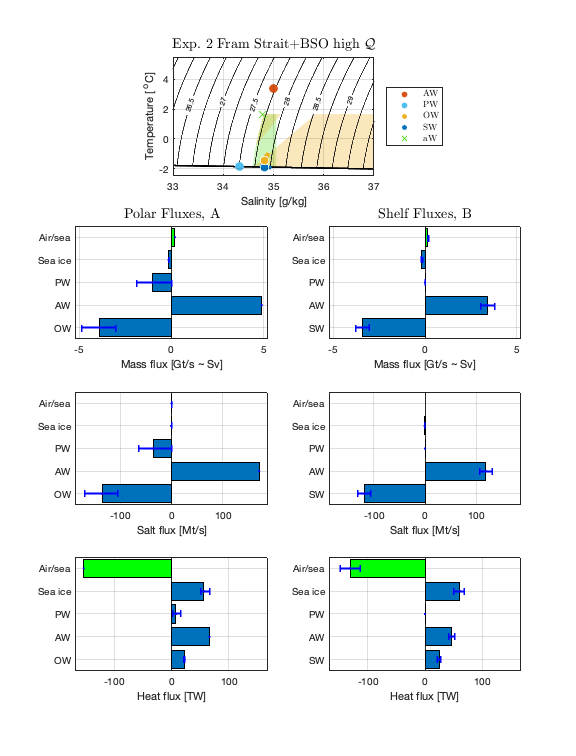

plot_POC_solution(model2) ;

Exp W: Eldevik & Nilsen (2013) parameters

modelW = build_POC_model('NH_FSBSO_EN13') ;

 Solutions for experiment: [Exp.~W Fram Strait+BSO] with file suffices: [NH_FSBSO_EN13]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:                      7.0000          |           35.2000          |            8.5000
 Atlantic Water to shelf:             7.0000          |           35.2000          |   6.5199   6.5220   6.5240
 Polar    Water:                     -1.8221          |           33.5407          |  -0.0149  -0.0149  -0.0149
 Overflow Water:            -0.5021  -0.5021  -0.5021 |  34.6475  34.6475  34.6475 |  -8.6188  -8.6188  -8.6188
 Shelf    Water:            -1.8863  -1.8863  -1.8863 |  34.6460  34.6460  34.6460 |  -6.6221  -6.6221  -6.6221
 Ambient Water:                       4.0887          |           34.6524          |
 Sea ice:                           -10.000

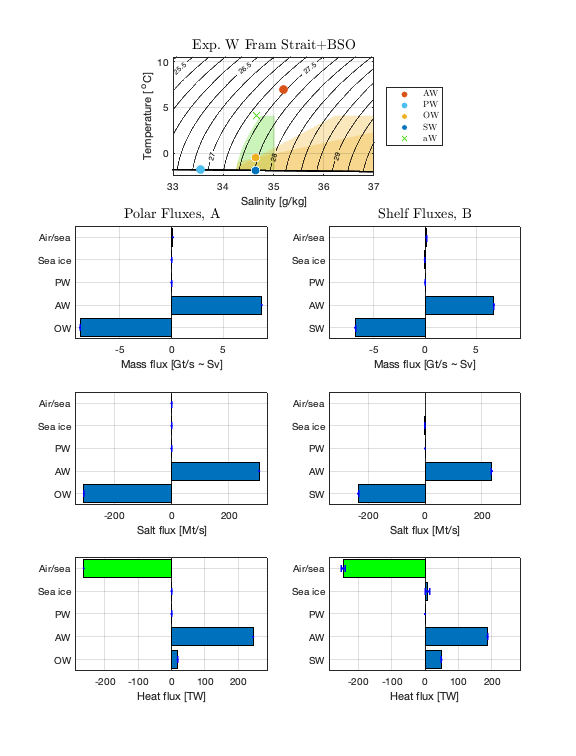

plot_POC_solution(modelW)

Exp X: Modified Northern hemisphere Fram Strait/Barents Sea Opening (intermediate Q).

modelX = build_POC_model('NH_FSBSO_int') ;

 Solutions for experiment: [Exp.~X Fram Strait+BSO intermediate ${\cal Q}$] with file suffices: [NH_FSBSO_int]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:                      3.4000          |           35.0000          |            4.7500
 Atlantic Water to shelf:             3.4000          |           35.0000          |   0.0141   0.0471   2.1233
 Polar    Water:                     -1.8675          |           34.3235          |  -4.4589  -4.4061  -0.0046
 Overflow Water:            -0.0021   1.4085   1.6355 |  34.8068  34.8277  34.9595 |  -4.7302  -0.4207  -0.3690
 Shelf    Water:            -1.8994  -1.9361  -2.2015 |  34.8711  35.5010  40.0000 |  -2.0896  -0.0296  -0.0025
 Ambient Water:                       1.6617          |           34.7768          |
 Sea ice:           

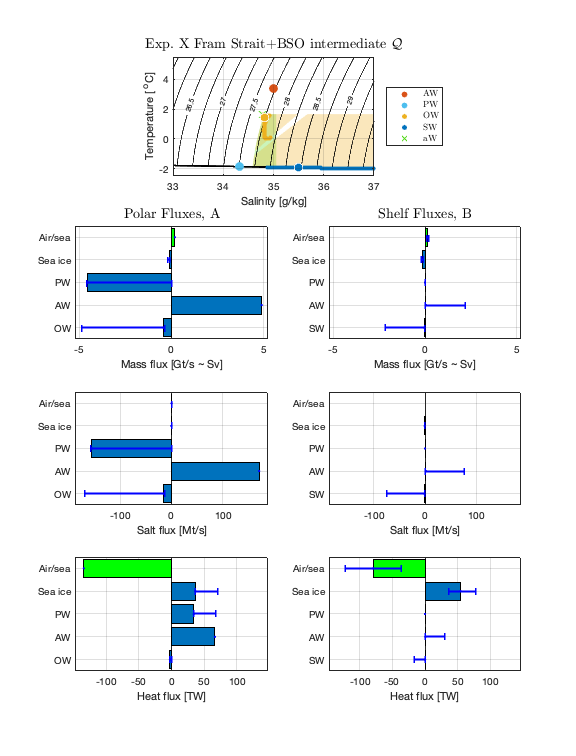

plot_POC_solution(modelX)

Make figure showing entrainment/shelf circulation tradeoff

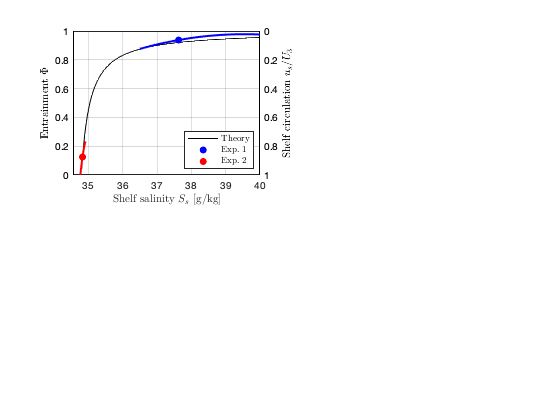

plot_POC_tradeoff(model1,model2)

Exp 3: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values.

model3 = build_POC_model('NH_FSBSO_range') ;

 Solutions for experiment: [Exp.~3 Fram Strait+BSO various ${\cal Q}$] with file suffices: [NH_FSBSO_range]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   4.7500   4.7500   4.7500
 Atlantic Water to shelf:    3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   0.0106   1.5568   4.7388
 Polar    Water:            -1.8675  -1.8675  -1.8675 |  34.3235  34.3235  34.3235 |  -4.8302  -1.8764  -0.0000
 Overflow Water:            -1.8966   0.0502   1.6355 |  34.5892  34.8606  35.1110 |  -4.7494  -2.9042  -0.0036
 Shelf    Water:            -1.8828  -1.9595  -2.2015 |  34.5853  35.8998  40.0000 |  -4.7423  -1.5391  -0.0000
 Ambient Water:              1.6617   1.6617   1.6617 |  34.7768  34.7768  34.7768 | 
 Sea ice:    

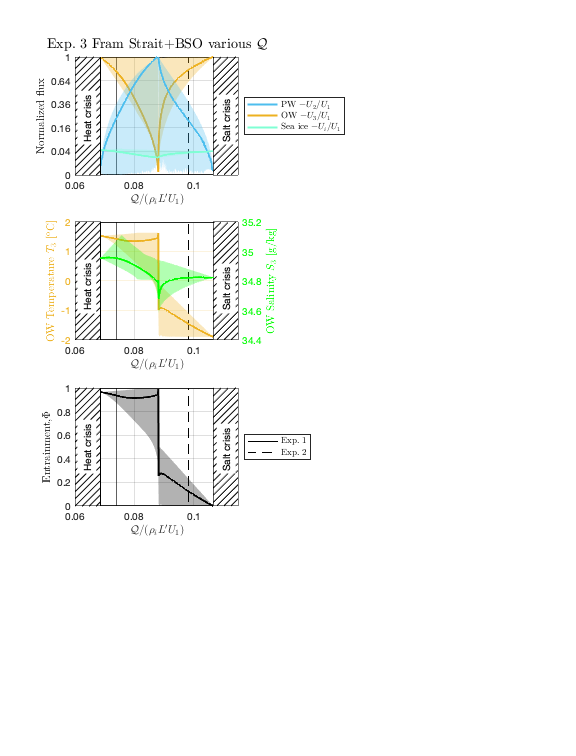

plot_POC_solutions1(model3,model1,model2)

Exp 4: Northern hemisphere Fram Strait/Barents Sea Opening with wide range of all parameters.

model4 = build_POC_model('NH_FSBSO_sens') ;

 Solutions for experiment: [Exp.~4 Fram Strait+BSO sensitivity] with file suffices: [NH_FSBSO_sens]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             2.5500   3.5417   4.5333 |  34.3000  35.0000  35.7000 |   3.1667   5.1458   7.1250
 Atlantic Water to shelf:    2.5500   3.5417   4.5333 |  34.3000  35.0000  35.7000 |   0.0000   1.9014   7.1246
 Polar    Water:            -1.9174  -1.8654  -1.8129 |  33.3813  34.2866  35.1791 |  -7.3082  -2.0430  -0.0000
 Overflow Water:            -1.9483   0.0488   2.4289 |  33.7579  34.8469  35.9065 |  -7.1726  -3.4186  -0.0000
 Shelf    Water:            -1.8347  -1.9558  -2.2015 |  33.7579  35.8370  39.9999 |  -7.1559  -1.8838  -0.0000
 Ambient Water:              1.0758   1.7573   2.4391 |  33.9968  34.7646  35.5281 | 
 Sea ice:            

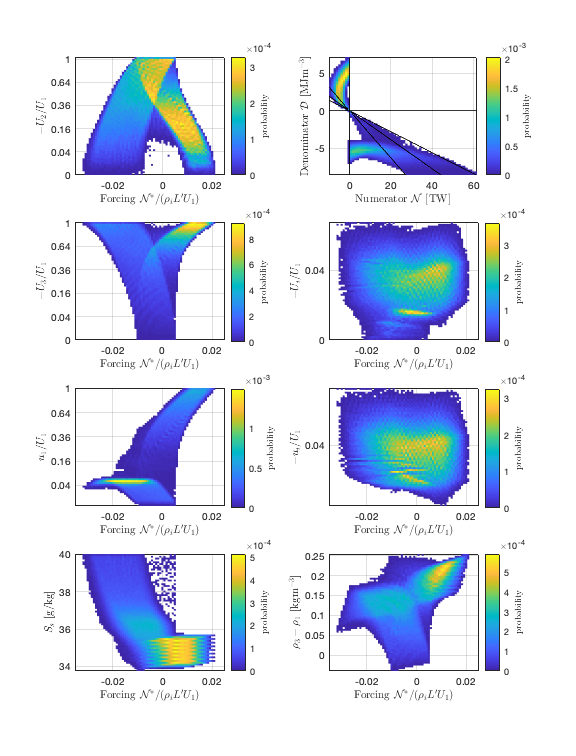

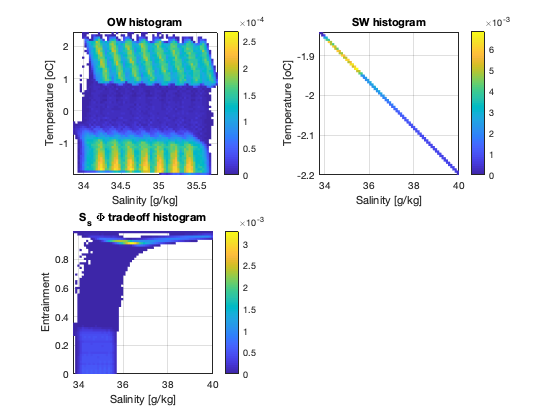

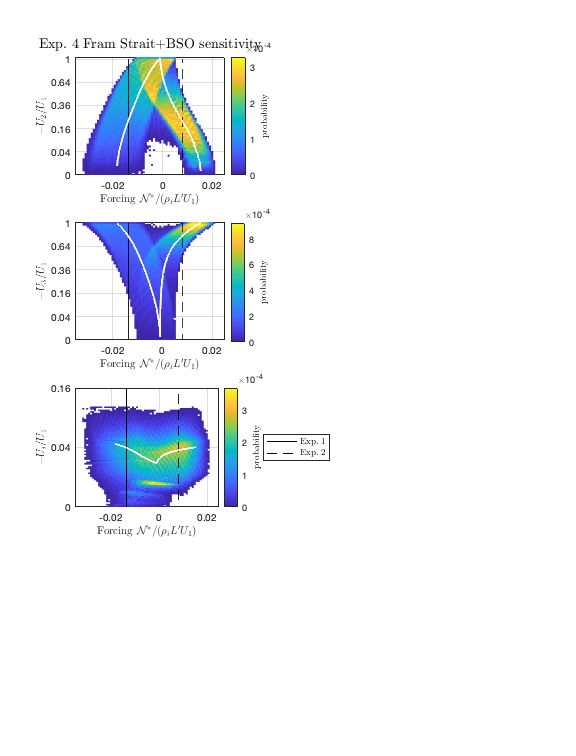

plot_POC_solutions2(model4,model3,model1,model2)

Compare numerical results to theory

 Exp.~4 has [525199] solutions, found: [215] salt crises, [101] heat crises, [646] OW emergencies.


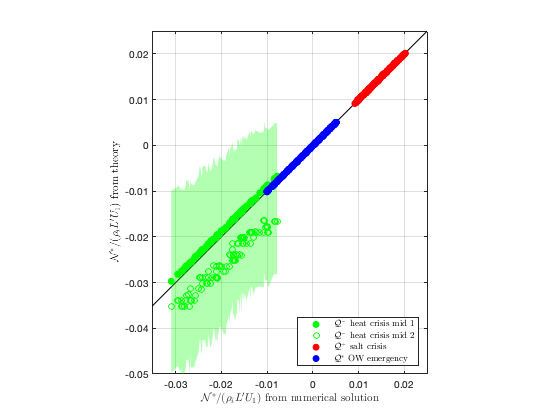

plot_POC_solutions_and_theory(model4)

Exp 5: Northern hemisphere Fram Strait/Barents Sea Opening with various S_2 values.

model5 = build_POC_model('NH_FSBSO_S2_range') ;

 Solutions for experiment: [Exp.~5 Fram Strait+BSO various $S_2$] with file suffices: [NH_FSBSO_S2_range]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   4.7500   4.7500   4.7500
 Atlantic Water to shelf:    3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   0.0171   0.9230   1.8245
 Polar    Water:            -1.8675  -1.8096  -1.7518 |  30.3235  32.3235  34.3235 |  -4.4929  -1.6248  -0.0000
 Overflow Water:            -0.4580   0.7595   1.6043 |  34.6497  34.7868  35.0714 |  -4.7731  -3.1785  -0.3876
 Shelf    Water:            -1.8884  -1.9460  -2.2015 |  34.6814  35.6696  40.0000 |  -1.8062  -0.9007  -0.0102
 Ambient Water:              1.6617   1.6808   1.6999 |  34.1168  34.4468  34.7768 | 
 Sea ice:      

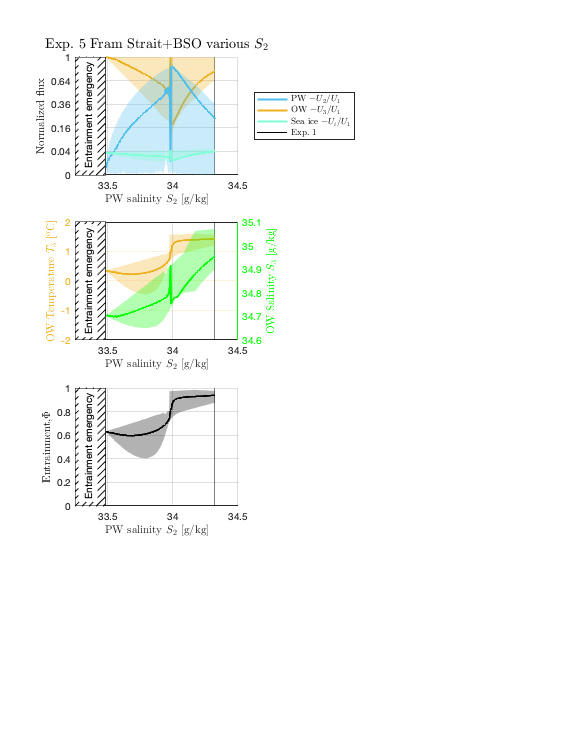

plot_POC_solutions3(model5,model1)

Exp Y: Modified Northern hemisphere Fram Strait/Barents Sea Opening (small S2).

modelY = build_POC_model('NH_FSBSO_small_S2') ;

 Solutions for experiment: [Exp.~Y Fram Strait+BSO small $S_2$] with file suffices: [NH_FSBSO_small_S2]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:                      3.4000          |           35.0000          |            4.7500
 Atlantic Water to shelf:             3.4000          |           35.0000          |   1.7748   1.7813   1.7842
 Polar    Water:                     -1.8189          |           32.6475          |  -0.0155  -0.0155  -0.0005
 Overflow Water:             0.3522   0.3522   0.3591 |  34.7023  34.7023  34.7032 |  -4.7726  -4.7584  -4.7584
 Shelf    Water:            -1.9097  -1.9097  -1.9100 |  35.0472  35.0472  35.0525 |  -1.7582  -1.7582  -1.7541
 Ambient Water:                       1.6778          |           34.5002          |
 Sea ice:                  

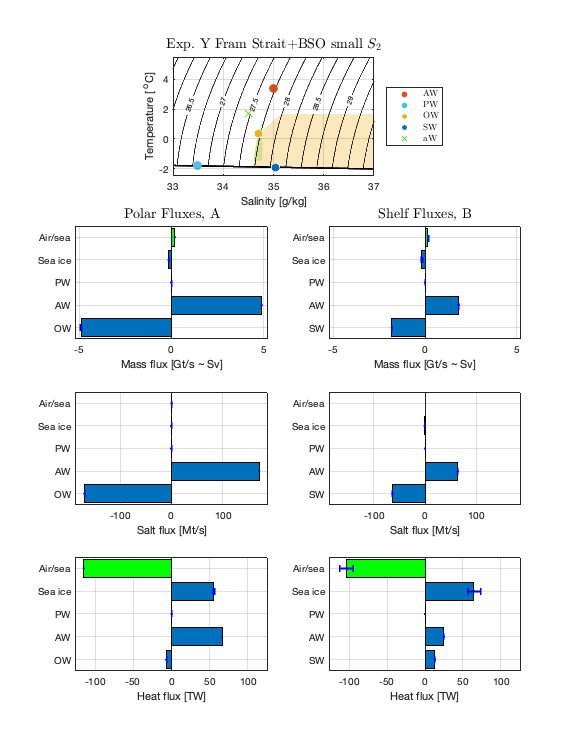

plot_POC_solution(modelY)

Exp 6: Southern hemisphere.

model6 = build_POC_model('SH_can') ;

 Solutions for experiment: [Exp.~6 Antarctic] with file suffices: [SH_can]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:                      0.5000          |           34.8386          |           26.0000
 Atlantic Water to shelf:             0.5000          |           34.8386          |   2.9349   6.5045   9.9675
 Polar    Water:                     -1.8868          |           34.6548          | -23.1477 -15.7313  -0.0198
 Overflow Water:            -1.8731  -1.2997  -0.8552 |  34.7965  34.8998  35.0318 | -25.7961 -10.3110  -2.9648
 Shelf    Water:            -1.8951  -1.9053  -1.9370 |  34.7969  34.9727  35.5158 |  -9.7619  -6.4507  -2.9242
 Ambient Water:                      -0.2876          |           34.7780          |
 Sea ice:                           -10.0000          | 

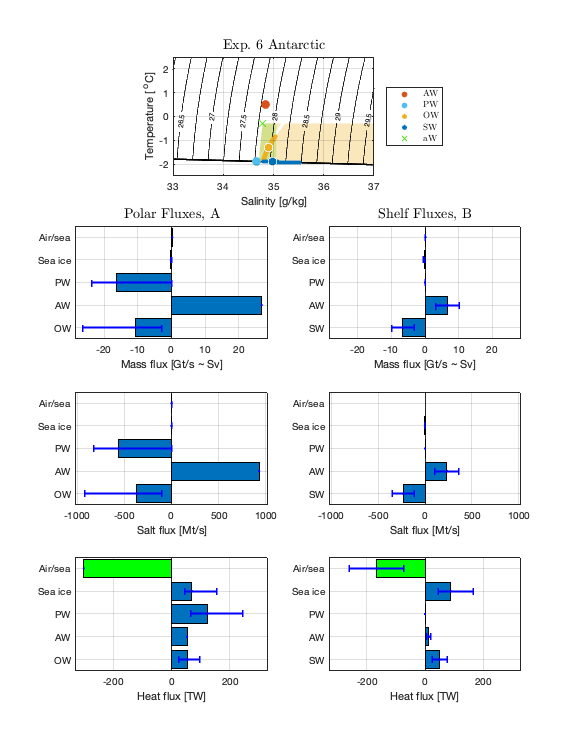

plot_POC_solution(model6)

Exp Z: Southern hemisphere with many Q values

modelZ = build_POC_model('SH_range') ;

 Solutions for experiment: [Exp.~7 Antarctic various ${\cal Q}$] with file suffices: [SH_range]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
 Atlantic Water:             0.5000   0.5000   0.5000 |  34.8386  34.8386  34.8386 |  26.0000  26.0000  26.0000
 Atlantic Water to shelf:    0.5000   0.5000   0.5000 |  34.8386  34.8386  34.8386 |   0.0124  10.0864  25.9607
 Polar    Water:            -1.8868  -1.8868  -1.8868 |  34.6548  34.6548  34.6548 | -26.1265  -9.4707  -0.0000
 Overflow Water:            -1.9056  -1.0998  -0.2912 |  34.7205  34.9328  35.1176 | -25.8574 -16.4931  -0.0000
 Shelf    Water:            -1.8906  -1.9618  -2.2015 |  34.7193  35.9396  40.0000 | -25.8084  -9.9845  -0.0000
 Ambient Water:             -0.2876  -0.2876  -0.2876 |  34.7780  34.7780  34.7780 | 
 Sea ice:                

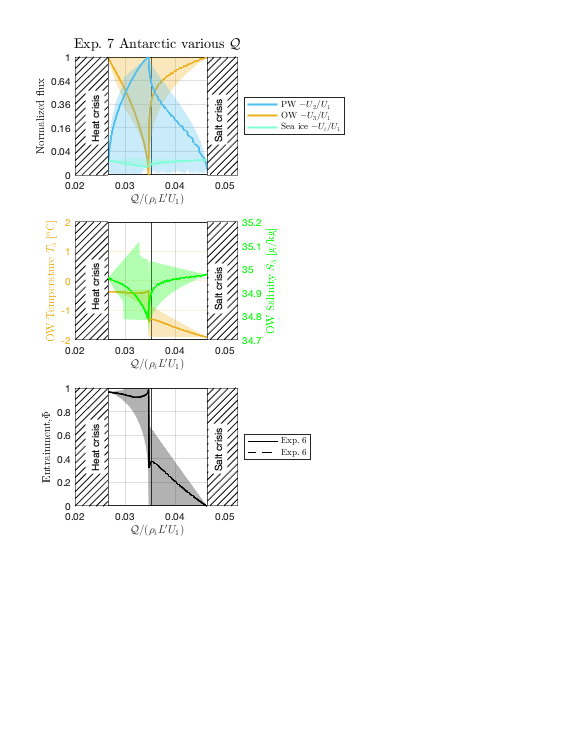

plot_POC_solutions1(modelZ,model6,model6)